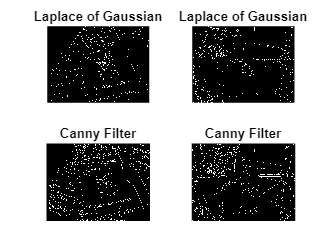

% Question 1
imdata1 = imread("book.jpg");
imgray1 = rgb2gray(imdata1);
% im1 = im2double(imgray1);

imdata2 = imread("red_chair.jpg");
imgray2 = rgb2gray(imdata2);
% im2 = im2double(imgray2);

log1=edge(im1,"log");
log2 = edge(im2,"log");

canny1=edge(im1,"canny");
canny2 = edge(im2,"canny");

figure(1);
subplot(2,2,1)
imshow(log1);
title("Laplace of Gaussian")
subplot(2,2,2)
imshow(log2)
title("Laplace of Gaussian")
subplot(2,2,3)
imshow(canny1);
title("Canny Filter")
subplot(2,2,4)
imshow(canny2)
title("Canny Filter")

There seems to be more noise when using the canny filter, but the edges of the objects in the image are more defined. On the other hand, the Laplace of Gaussian (LoG) filter was able to find the edges of the objects, but they're less well-defined and lacks more detail. 